clc; clear; close all;

參數

student_id = 01;
full_id ='B812111001';
my_name = '張博翔';  
class_name = '電機三乙';

% 計算
theta_z_deg = student_id + 50;
theta_z_rad = deg2rad(theta_z_deg);

V1 = 1.2;
V2 = 0.8;
abs_Z = 1.0;

% 圓心與半徑
% C1 (送電端圓心) V1^2 / Z*
C1 = (V1^2) / (abs_Z * exp(-1j * theta_z_rad)); 
C1_mag = abs(C1);

% C2 (受電端圓心) -V2^2 / Z*
C2 = - (V2^2) / (abs_Z * exp(-1j * theta_z_rad)); 
C2_mag = abs(C2);

% |B|(半徑) V1*V2/Z
B_val = (V1 * V2) / abs_Z; 

% 圓軌跡
delta = linspace(0, 2*pi, 360); 

% S12 = C1 - |B| * e^j(theta_z + theta12)
S12_circle = C1 - B_val * exp(1j * (theta_z_rad + delta));
% -S21 = C2 + |B| * e^j(theta_z - theta12)
nS21_circle = C2 + B_val * exp(1j * (theta_z_rad - delta));

% theta12 = 0
S12_zero = C1 - B_val * exp(1j * (theta_z_rad + 0));
nS21_zero = C2 + B_val * exp(1j * (theta_z_rad - 0));

% P12 max
theta_P12max = 180 - theta_z_deg; 
P12_max_val = real(C1) + B_val;
S12_max_point = C1 - B_val * exp(1j * deg2rad(theta_z_deg + theta_P12max));

% -P21 max
theta_nP21max = theta_z_deg;
nP21_max_val = real(C2) + B_val;
nS21_max_point = C2 + B_val * exp(1j * deg2rad(theta_z_deg - theta_nP21max));

繪圖  theata12 = 0;

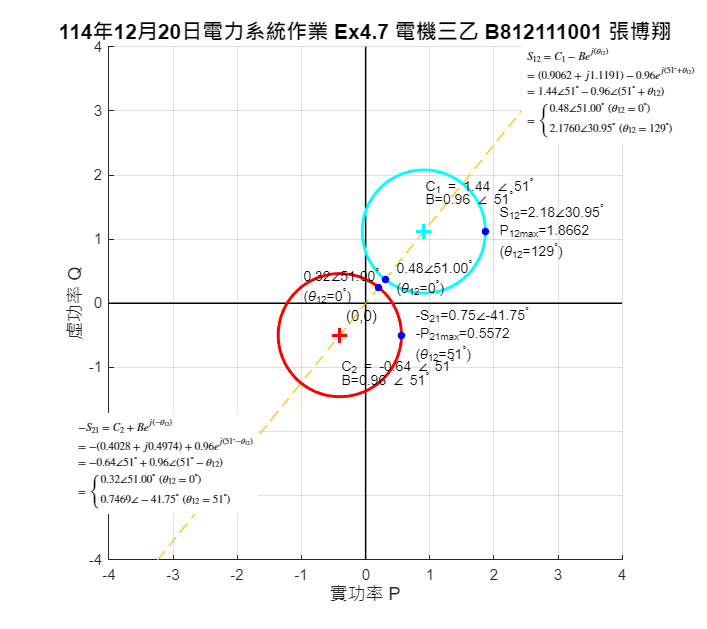

figure('Color', 'w', 'Position', [100, 50, 900, 800]);

hold on; grid on; axis equal;
axis([-4 4 -4 4]);
xlabel('實功率 P', 'FontSize', 12);
ylabel('虛功率 Q', 'FontSize', 12);

title_str = sprintf('114年12月20日電力系統作業 Ex4.7 %s %s %s', class_name, full_id, my_name);
title(title_str, 'FontSize', 14, 'FontWeight', 'bold');

plot([-5 5], [0 0], 'k', 'LineWidth', 1); % X軸
plot([0 0], [-5 5], 'k', 'LineWidth', 1); % Y軸
text(-0.3, -0.2, '(0,0)', 'FontSize', 10);

% 阻抗角線theta_z (51度)
L = 6;
plot([-L*cos(theta_z_rad), L*cos(theta_z_rad)], ...
     [-L*sin(theta_z_rad), L*sin(theta_z_rad)], ...
     'Color', [1, 0.75, 0], 'LineStyle', '--', 'LineWidth', 0.5);

% 繪製圓與圓心
plot(real(S12_circle), imag(S12_circle), 'c', 'LineWidth', 2);
plot(real(nS21_circle), imag(nS21_circle), 'r', 'LineWidth', 2);

plot(real(C1), imag(C1), 'c+', 'MarkerSize', 10, 'LineWidth', 2);
plot(real(C2), imag(C2), 'r+', 'MarkerSize', 10, 'LineWidth', 2);

%S12
str_S12 = {
    '$S_{12} = C_1 - B e^{j(\theta_{12})}$';
    sprintf('$ = (%.4f + j%.4f) - %.2f e^{j(%d^{\\circ}+\\theta_{12})}$', real(C1), imag(C1), B_val, theta_z_deg);
    sprintf('$ = %.2f\\angle%d^{\\circ} - %.2f\\angle(%d^{\\circ}+\\theta_{12})$', C1_mag, theta_z_deg, B_val, theta_z_deg);
    ['$ = \left\{ \begin{array}{l} ' ...
     sprintf('%.2f\\angle%.2f^{\\circ} \\; (\\theta_{12}=0^{\\circ})', abs(S12_zero), rad2deg(angle(S12_zero))) ...
     ' \\ ' ...
     sprintf('%.4f\\angle%.2f^{\\circ} \\; (\\theta_{12}=%d^{\\circ})', abs(S12_max_point), rad2deg(angle(S12_max_point)), round(theta_P12max)) ...
     ' \end{array} \right. $']
};

text(2.5, 4.0, str_S12, 'Interpreter', 'latex', 'FontSize', 7, ...
    'BackgroundColor', 'w', 'EdgeColor', 'none', 'Margin', 3, 'VerticalAlignment', 'top');

text(real(C1), imag(C1)+0.7, ...
    {sprintf('C_1 = %.2f \\angle %d^{\\circ}', C1_mag, theta_z_deg)}, 'Interpreter', 'tex', 'FontSize', 9);


text(real(C1), imag(C1)+0.5, sprintf('B=%.2f \\angle %d^{\\circ}', B_val, theta_z_deg), 'Interpreter', 'tex', 'FontSize', 9);

% P12 max
plot(real(S12_max_point), imag(S12_max_point), 'b.', 'MarkerSize', 15);
text(real(S12_max_point)+0.2, imag(S12_max_point), ...
    sprintf('S_{12}=%.2f\\angle%.2f^{\\circ}\nP_{12max}=%.4f\n(\\theta_{12}=%d^{\\circ})', ...
    abs(S12_max_point), rad2deg(angle(S12_max_point)), P12_max_val, round(theta_P12max)), ...
    'Interpreter', 'tex', 'FontSize', 9);

% theta12=0
plot(real(S12_zero), imag(S12_zero), 'b.', 'MarkerSize', 15, 'MarkerFaceColor', 'w');
text(real(S12_zero)+0.15, imag(S12_zero), ...
sprintf('%.2f\\angle%.2f^{\\circ}\n(\\theta_{12}=0^{\\circ})', ...
abs(S12_zero), rad2deg(angle(S12_zero))), 'Interpreter', 'tex', 'FontSize', 9);


% -S21
str_S21 = {
    '$-S_{21} = C_2 + B e^{j(- \theta_{12})}$';
    sprintf('$ = -(%.4f + j%.4f) + %.2f e^{j(%d^{\\circ}-\\theta_{12})}$', -real(C2), -imag(C2), B_val, theta_z_deg);
    sprintf('$ = -%.2f\\angle%d^{\\circ} + %.2f\\angle(%d^{\\circ}-\\theta_{12})$', abs(C2), theta_z_deg, B_val, theta_z_deg);
    ['$ = \left\{ \begin{array}{l} ' ...
     sprintf('%.2f\\angle%.2f^{\\circ} \\; (\\theta_{12}=0^{\\circ})', abs(nS21_zero), rad2deg(angle(nS21_zero))) ...
     ' \\ ' ...
     sprintf('%.4f\\angle%.2f^{\\circ} \\; (\\theta_{12}=%d^{\\circ})', abs(nS21_max_point), rad2deg(angle(nS21_max_point)), round(theta_nP21max)) ...
     ' \end{array} \right. $']
};

text(-4.5, -2.5, str_S21, 'Interpreter', 'latex', 'FontSize', 7, ...
    'BackgroundColor', 'w', 'EdgeColor', 'none', 'Margin', 3);

text(real(C2), imag(C2)-0.5, ...
    {sprintf('C_2 = -%.2f \\angle %d^{\\circ}', abs(C2), theta_z_deg)}, 'Interpreter', 'tex', 'FontSize', 9);

text(real(C2), imag(C2)-0.7, sprintf('B=%.2f \\angle %d^{\\circ}', B_val, theta_z_deg), 'Interpreter', 'tex', 'FontSize', 9);

% -P21 max
plot(real(nS21_max_point), imag(nS21_max_point), 'b.', 'MarkerSize', 15);
text(real(nS21_max_point)+0.2, imag(nS21_max_point), ...
    sprintf('-S_{21}=%.2f\\angle%.2f^{\\circ}\n-P_{21max}=%.4f\n(\\theta_{12}=%d^{\\circ})', ...
    abs(nS21_max_point), rad2deg(angle(nS21_max_point)), nP21_max_val, round(theta_nP21max)), ...
    'Interpreter', 'tex', 'FontSize', 9);

% 標記 theta=0
plot(real(nS21_zero), imag(nS21_zero), 'b.', 'MarkerSize', 15, 'MarkerFaceColor', 'w');
text(real(nS21_zero)-1.2, imag(nS21_zero), ...
    sprintf('%.2f\\angle%.2f^{\\circ}\n(\\theta_{12}=0^{\\circ})', ...
    abs(nS21_zero), rad2deg(angle(nS21_zero))), 'Interpreter', 'tex', 'FontSize', 9);

hold off;